# Late self-similar solution for the drainage of an unconfined aquifer

set_demo_defaults, clear

This example follows the paper Zheng et al. (2013). We consider the drainage of an unconfined linear aquifer with vertical variation in both porosity and hydraulic conductivity.  Any vertical property variation can be accomodated, but here we assume the form a power-laws

$\phi(z) = \phi_0 z^m$ and $K(z) = K_0z^n$ where typically $n/m \in\left[2,\,3\right]$. 

m_vec = linspace(0,3,7)

m_vec =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000


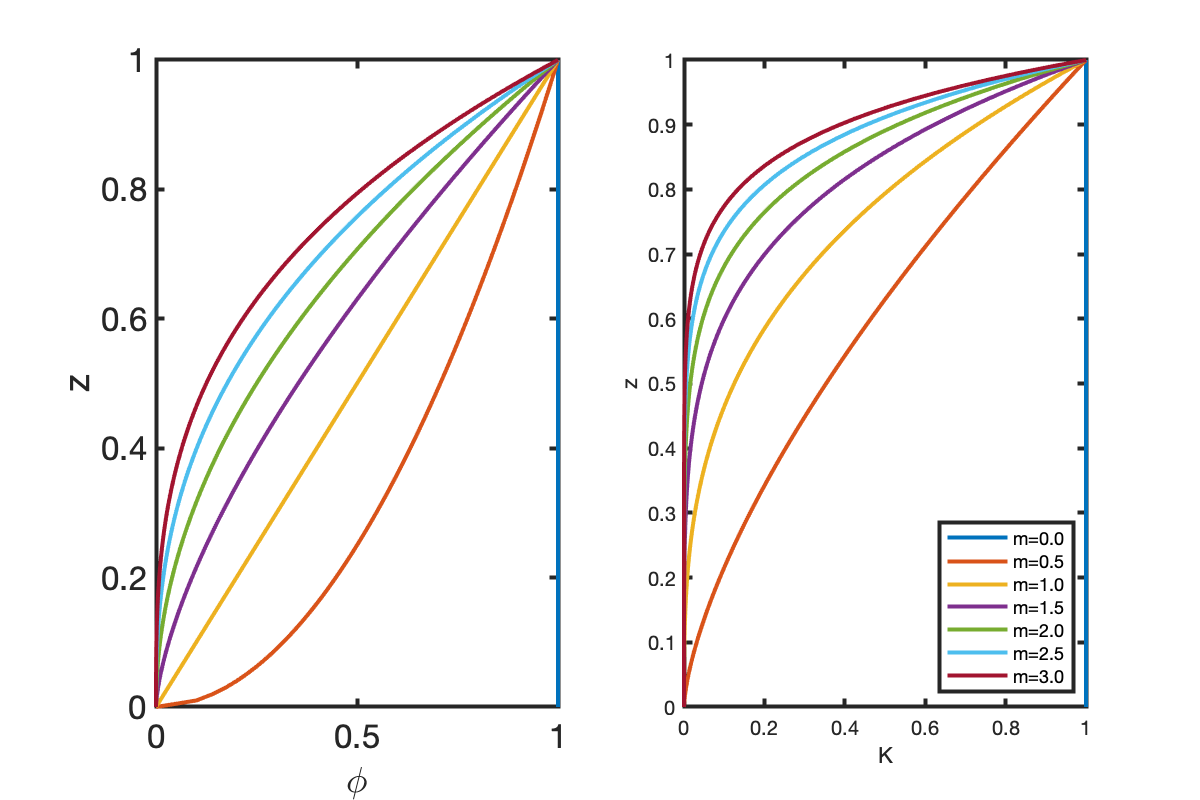

n_vec = 3*m_vec;
z = linspace(0,1,1e2);

figure('position',[10 10 600 400])
for i=1:length(m_vec)
subplot 121
plot(z.^m_vec(i),z), hold on
xlabel '\phi'
ylabel 'z'

subplot 122
plot(z.^n_vec(i),z), hold on
xlabel 'K'
ylabel 'z'
end
legend('m=0.0','m=0.5','m=1.0','m=1.5','m=2.0','m=2.5','m=3.0','location','southeast')

This allows for self-similar solutions that give insight and can be used to check the numerical simulations. The vertically integrated fluid mass balance id given by

$\frac{\partial }{\partial t}\int_0^{h} \phi(z)\, \mathrm{d}z - \int_0^{h} K(z) \nabla h\,  \mathrm{d}z = 0$ on $x\in\left[0,\,l\right]$

Integrating we can write the accumulation term several ways

 
$$\frac{\partial}{\partial t}\int_0^h\phi(z)\,\mathrm{d}z = \frac{\phi_0}{m+1}\frac{\partial h^{m+1}}{\partial t} = \phi_0 h^m \frac{\partial h}{\partial t} = \phi(h)  \frac{\partial h}{\partial t} $$


where the last expression shows that the porosity takes the role of the storativity in an unconfined aquifer. Integrating the flux term we obtain


$$- \int_0^{h} K(z) \nabla h\,  \mathrm{d}z = -\frac{K_0}{n+1}h^{n+1}\nabla h$$


The governing equation can then be written as

$\frac{\partial h^{m+1}}{\partial t}-D_h\nabla\cdot\left[h^{n+1}\nabla h\right] = 0$ on $x\in\left[0,\,l\right]$

where $D_h = \frac{K_0(m+1)}{\phi_0(n+1)}$ is the effective hydraulic diffusivity of the aquifer.

## Late self-similar solution

This problem has a both an early and a late self-similar solution. The early solution was governs the initial resonse before the change in the head interacts with the other boundary. The late self-similar solution becomes relevant once the head is dropping across the entire aquifer

% make grid so that last cell center is exactly 1;
Nx = 200;
dx = 1/(Nx-.5);
xmax = Nx*dx;

Grid.xmin = 0; Grid.xmax = xmax; Grid.Nx = Nx;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
fs = zeros(Grid.Nx,1);   % r.h.s
M = Grid.dx/2*abs(G);   % mean operator

%% Residual
F1  = @(u,n) spdiags(M*u.^(n+1),0,Nx+1,Nx+1);
f2  = @(u,n,m) (m+1)/(n-m+1)*u.^(m+1);
res = @(u,n,m) D*(F1(u,n)*G*u)+f2(u,n,m);

%% Boundary conditions - for update!
BC.dof_dir = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = 0;
BC.dof_neu = [];
BC.dof_f_neu = [];
BC.qb = [];
[B,N,I] = build_bnd(BC,Grid,I);

### Solve directly

Due to the arbitrary nature of the exponents the non-linearity of this ODE can be incresed until the Newton fails - at least for simple initial guesses. For the case of constant coefficients (m=0, n=0) the ODE is still non-linear, but converges after some initial iterations. If we increase m (n=3*m) the Newton takes more iterations and eventually fails to converge around m ~ 0.3.

% Note: This will break at m ~ 0.3
m = .0; n = 3*m; kmax= 30;
% initial guess
u = 1-Grid.xc;
u = solve_self_similar_ode(res,u,n,m,B,N,BC,kmax);

it = 1: nres = 1.99e+04  ndu = 8.12e+00
it = 2: nres = 4.97e+03  ndu = 3.60e+00
it = 3: nres = 1.24e+03  ndu = 1.28e+00
it = 4: nres = 3.04e+02  ndu = 3.42e-01
it = 5: nres = 6.27e+01  ndu = 7.82e-02
it = 6: nres = 5.08e+00  ndu = 1.33e-02
it = 7: nres = 2.81e-02  ndu = 8.12e-04
it = 8: nres = 8.34e-07  ndu = 3.87e-06
it = 9: nres = 5.73e-11  ndu = 1.13e-10


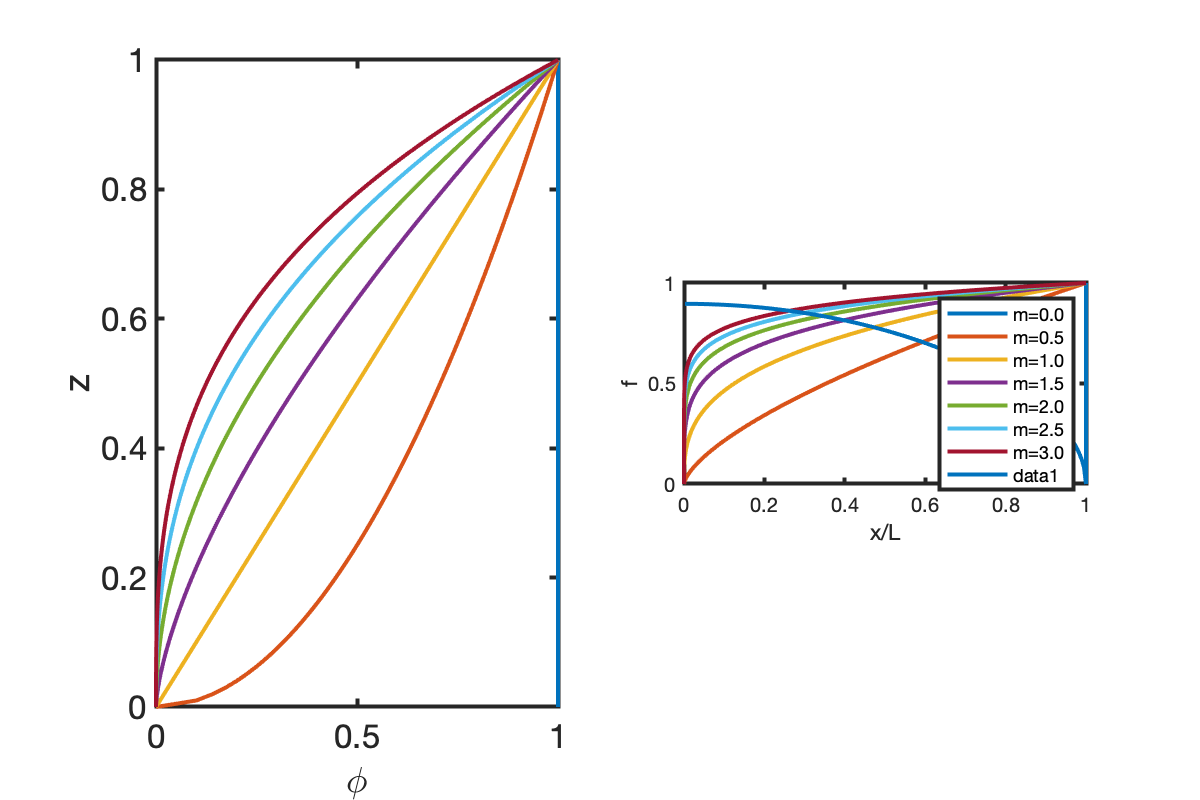

plot_self_similar_soln(Grid,u,n,m)

### Load stepping

A common strategy to deal with the failure of Newton-Raphson to converge for the more non-linear problems if called **load stepping**.The term comes  from mechanics where Newton-Raphson may fail to converge for large loads that cause large deformations. The idea is simply to gradually apply larger loads and always use the previous solution as an initial guess. 

In our case, we can start with the simpler case $m=n=0$ and then gradually increase $m$ ($n=3m$) to the desired value, taking as many steps as are necessary for Newton-Raphson to converge to the next solution. This load stepping approach is implemented below.

%% Load stepping
Nload = 7;
Niter = 15;
m_vec = linspace(0,3,Nload);
n_vec = 3*m_vec;

% initial guess
u = 1-Grid.xc;
U = zeros(Grid.Nx,Nload);

for i=1:Nload
    fprintf('Solving for m = %3.1f and n=%3.1f:\n',m_vec(i),n_vec(i))
    u = solve_self_similar_ode(res,u,n_vec(i),m_vec(i),B,N,BC,kmax);
    U(:,i) = u;
    fprintf('\n\n')
end

Solving for m = 0.0 and n=0.0:


it = 1: nres = 1.99e+04  ndu = 8.12e+00
it = 2: nres = 4.97e+03  ndu = 3.60e+00
it = 3: nres = 1.24e+03  ndu = 1.28e+00
it = 4: nres = 3.04e+02  ndu = 3.42e-01
it = 5: nres = 6.27e+01  ndu = 7.82e-02
it = 6: nres = 5.08e+00  ndu = 1.33e-02
it = 7: nres = 2.81e-02  ndu = 8.12e-04
it = 8: nres = 8.34e-07  ndu = 3.87e-06
it = 9: nres = 5.73e-11  ndu = 1.13e-10


Solving for m = 0.5 and n=1.5:


it = 1: nres = 5.97e+04  ndu = 9.85e+00
it = 2: nres = 1.84e+04  ndu = 3.56e+00
it = 3: nres = 5.67e+03  ndu = 1.94e+00
it = 4: nres = 1.74e+03  ndu = 9.30e-01
it = 5: nres = 5.34e+02  ndu = 4.43e-01
it = 6: nres = 1.56e+02  ndu = 2.01e-01
it = 7: nres = 3.51e+01  ndu = 7.55e-02
it = 8: nres = 3.01e+00  ndu = 1.73e-02
it = 9: nres = 2.10e-02  ndu = 1.24e-03
it = 10: nres = 9.02e-07  ndu = 7.48e-06
it = 11: nres = 1.10e-10  ndu = 3.28e-10


Solving for m = 1.0 and n=3.0:


it = 1: nres = 1.34e+03  ndu = 2.23e+00
it = 2: nres = 4.37e+02  ndu = 6.50e-01
it = 3: nres = 1.36e+02  ndu = 2.33e-01
it = 4: nres = 3.25e+01  ndu = 7.76e-02
it = 5: nres = 3.01e+00  ndu = 1.80e-02
it = 6: nres = 2.39e-02  ndu = 1.42e-03
it = 7: nres = 1.38e-06  ndu = 1.03e-05
it = 8: nres = 1.40e-10  ndu = 6.12e-10


Solving for m = 1.5 and n=4.5:


it = 1: nres = 2.75e+02  ndu = 9.45e-01
it = 2: nres = 8.52e+01  ndu = 2.33e-01
it = 3: nres = 1.84e+01  ndu = 6.22e-02
it = 4: nres = 1.16e+00  ndu = 1.09e-02
it = 5: nres = 3.82e-03  ndu = 5.48e-04
it = 6: nres = 5.16e-08  ndu = 1.64e-06
it = 7: nres = 2.19e-10  ndu = 2.70e-11


Solving for m = 2.0 and n=6.0:


it = 1: nres = 1.16e+02  ndu = 4.99e-01
it = 2: nres = 3.08e+01  ndu = 1.09e-01
it = 3: nres = 3.52e+00  ndu = 2.14e-02
it = 4: nres = 4.20e-02  ndu = 1.78e-03
it = 5: nres = 4.83e-06  ndu = 1.74e-05
it = 6: nres = 2.51e-10  ndu = 1.98e-09


Solving for m = 2.5 and n=7.5:


it = 1: nres = 6.71e+01  ndu = 3.01e-01
it = 2: nres = 1.44e+01  ndu = 5.93e-02
it = 3: nres = 8.28e-01  ndu = 8.60e-03
it = 4: nres = 2.15e-03  ndu = 3.54e-04
it = 5: nres = 2.22e-08  ndu = 7.92e-07


Solving for m = 3.0 and n=9.0:


it = 1: nres = 4.52e+01  ndu = 2.01e-01
it = 2: nres = 7.68e+00  ndu = 3.55e-02
it = 3: nres = 2.33e-01  ndu = 3.91e-03
it = 4: nres = 1.59e-04  ndu = 8.59e-05
it = 5: nres = 1.01e-09  ndu = 5.30e-08


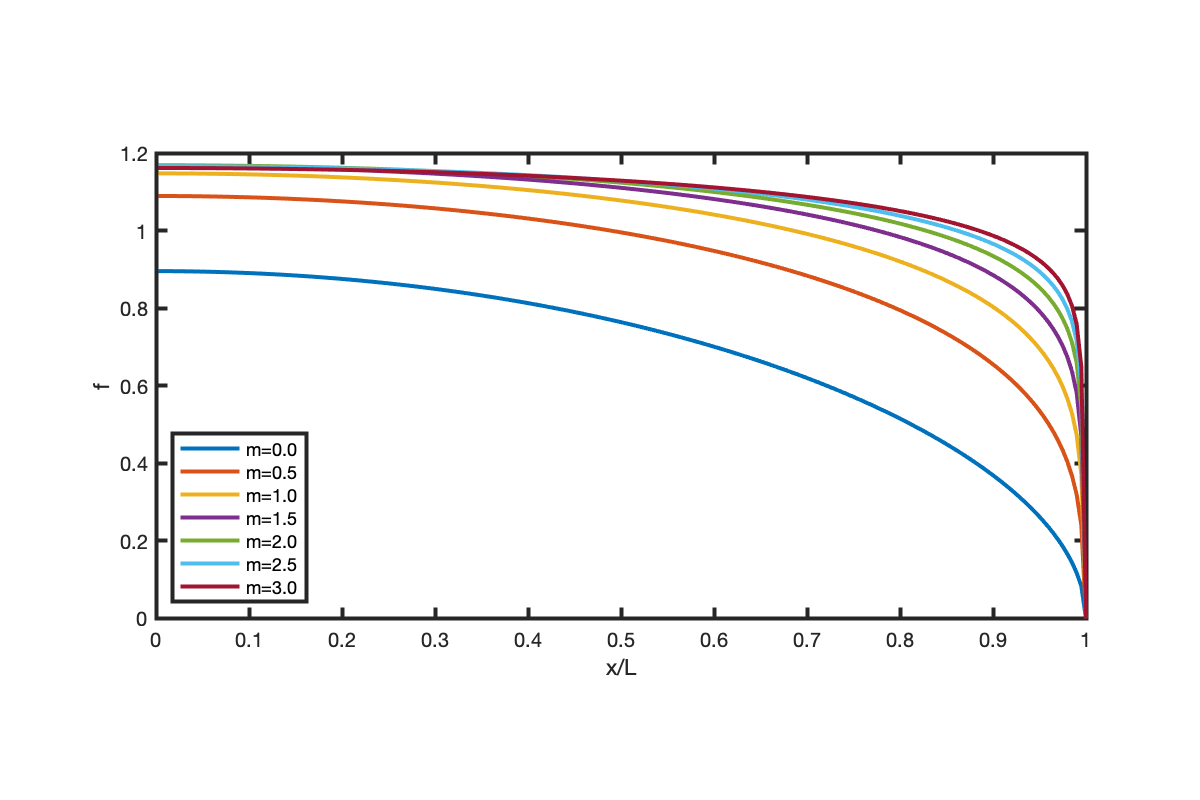

% plot solutions
figure('position',[10 10 600 400])
for i=1:Nload
    plot_self_similar_soln(Grid,U(:,i),n_vec(i),m_vec(i)), hold on
end
legend('m=0.0','m=0.5','m=1.0','m=1.5','m=2.0','m=2.5','m=3.0','location','southwest')

The self-similar solutions,$f(x/l)$, for increasing $m$ are shown in the figure. As $m$ increases the solution develops a strong boundary layer, but eventually changes less and less with increasing $m$.

## References

- Zheng et al. (2013) [Fluid drainage from the edge of a porous reservoir](https://doi.org/10.1017/jfm.2012.630), *J Fluid Mech*, **718**, ﻿558-568

## Auxillary functions

#### solve_self_similar_ode

function [u] = solve_self_similar_ode(res,u,n,m,B,N,BC,kmax)
eps_jac = 1e-6;     % perturbation for numerical Jacobian
tol = 1e-6;         % convergence tolerance

nres = norm(res(u,n,m)); ndu = 1; k = 0;
while (nres > tol || ndu > tol) && k < kmax
    Jac_num = comp_jacobian_selfsimilar(res,u,eps_jac,n,m);
    du = solve_lbvp(Jac_num,-res(u,n,m),B,BC.g,N); 
    u = u + du;
    nres = norm(N'*res(u,n,m)); ndu = norm(N'*du);
    k = k+1;
    fprintf('it = %d: nres = %3.2e  ndu = %3.2e\n',k,nres,ndu)
    if k == 1; ndu = 0; end % to allow exit on first iteration
end
if k == kmax; fprintf('Newton-Raphson did not converge in %d iterations.\n',k); end
end

#### plot_self_similar_soln

function [] = plot_self_similar_soln(Grid,u,n,m)


z = linspace(0,1,1e2);
% subplot('Position',[ode_x ode_y subW_ode/figW subH_ode/figH])
plot(Grid.xc,u,'-'), hold on
xlabel 'x/L'
ylabel 'f'
pbaspect([1 .5 1])


end

#### comp_jacobian_selfsimilar

function [J] = comp_jacobian_selfsimilar(r,u,eps,n,m)
N=length(u);
u_perturb=u;
for i=1:N
   u_perturb(i)=u_perturb(i)+eps;
   J(:,i)=(r(u_perturb,n,m)-r(u,n,m))/eps;
   u_perturb(i)=u(i);
end
end
